# Modelo De Calcio

% Preparación del entorno
clear;
clc;
close all;

% Definición simbólica del sistema
syms p53 Stat3 Np63 Pstat3 DNp63
assume(Pstat3 >= 0 & DNp63 >= 0)

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Número de muestras
nSamples = 400;

## Muestreo usando Linspace

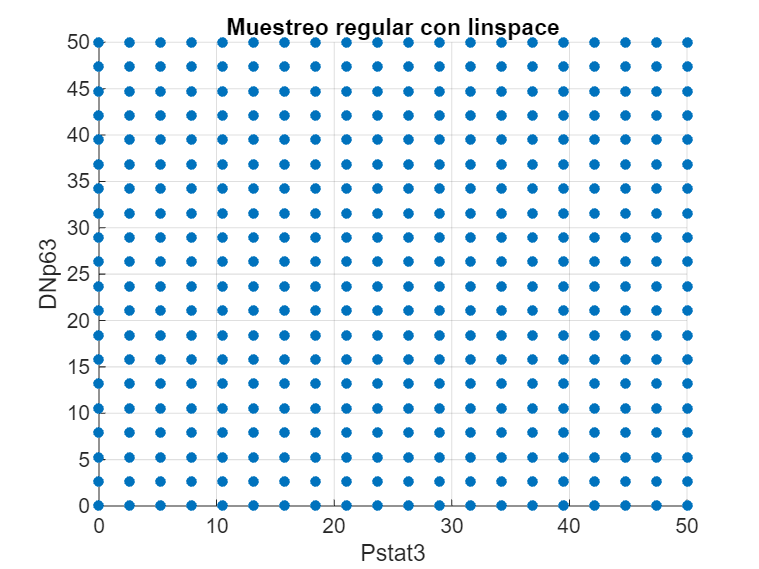

Pstat3_vals = linspace(0, 50, sqrt(nSamples));
DNp63_vals = linspace(0, 50, sqrt(nSamples));

% Crear grilla de combinaciones
[Pstat3_grid, DNp63_grid] = meshgrid(Pstat3_vals, DNp63_vals);
Pstat3_vals = Pstat3_grid(:);
DNp63_vals = DNp63_grid(:);

% Visualización
figure;
scatter(Pstat3_vals, DNp63_vals, 25, 'filled');
xlabel('Pstat3');
ylabel('DNp63');
title('Muestreo regular con linspace');
grid on;

## Muestreo usando Hipercubo Latino

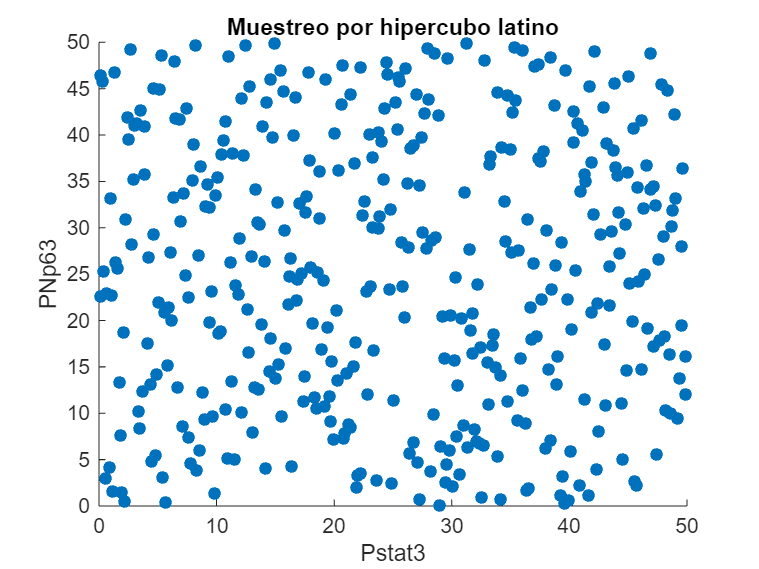

% Genera muestreo por hipercubo latino en [0,1]x[0,1]
lhsPoints = lhsdesign(nSamples, 2);  % 2 dimensiones: Pstat3 y DNp63

% Escalar a [0, 50]
Pstat3_vals = 50 * lhsPoints(:,1);
DNp63_vals = 50 * lhsPoints(:,2);

% Visualizar distribución de puntos
figure;
scatter(Pstat3_vals, DNp63_vals, 'filled');
xlabel('Pstat3');
ylabel('PNp63');
title('Muestreo por hipercubo latino');

## Puntos de equilibrio por par de parámetros 

% Inicializar resultados
resultados = []; % Para almacenar [Pstat3, PNp63, x1, x2, x3]

%% Bucle sobre las combinaciones
for i = 1:nSamples
    val_Pstat3 = Pstat3_vals(i);
    val_DNp63 = DNp63_vals(i);

    % Resolver el sistema con estos valores
    ecuaciones = [subs(f1, [Pstat3, DNp63], [val_Pstat3, val_DNp63]) == 0, ...
                  subs(f2, [Pstat3, DNp63], [val_Pstat3, val_DNp63]) == 0, ...
                  subs(f3, [Pstat3, DNp63], [val_Pstat3, val_DNp63]) == 0];

    % Semillas iniciales para intentar múltiples soluciones
    seeds = [
        0.1 0.1 0.1;
        1   1   1;
        5   5   5;
        10  10  10;
        20  20  20;
        30  30  30;
        40  40  40;
        50  50  50;
    ];

    sols_unicos = [];

    % Intentar resolver desde diferentes semillas
    for s = 1:size(seeds, 1)
        seed = seeds(s, :);

        try
            soluciones = vpasolve(ecuaciones, vars, seed);
            x1 = double(soluciones.p53);
            x2 = double(soluciones.Stat3);
            x3 = double(soluciones.Np63);

            if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
                nueva_sol = [x1 x2 x3];

                % Eliminar soluciones duplicadas por tolerancia
                if isempty(sols_unicos) || all(vecnorm(sols_unicos - nueva_sol, 2, 2) > 1e-3)
                    sols_unicos = [sols_unicos; nueva_sol];
                end
            end
        catch
            continue
        end
    end

    % Guardar todas las soluciones únicas para este punto de parámetros
    for j = 1:size(sols_unicos, 1)
        resultados = [resultados; val_Pstat3, val_DNp63, sols_unicos(j,:)];
    end
end

%% Mostrar resumen
resultados_tbl = array2table(resultados, ...
    'VariableNames', {'Pstat3', 'DNp63', 'p53', 'Stat3', 'Np63'});

% Contar número de soluciones por par de parámetros
[unique_pairs, ~, idx] = unique(resultados(:,1:2), 'rows');
num_equilibrios = accumarray(idx, 1);

% Mostrar algunos resultados
disp('Resumen de puntos de equilibrio por combinación de parámetros:')

Resumen de puntos de equilibrio por combinación de parámetros:


for i = 1:size(unique_pairs, 1)
    fprintf('Pstat3 = %.2f, DNp63 = %.2f → %d equilibrio(s)\n', ...
        unique_pairs(i,1), unique_pairs(i,2), num_equilibrios(i));
end

Pstat3 = 0.00, DNp63 = 2.63 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 5.26 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 7.89 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 10.53 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 13.16 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 15.79 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 18.42 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 21.05 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 23.68 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 26.32 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 28.95 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 31.58 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 34.21 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 36.84 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 39.47 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 42.11 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 44.74 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 47.37 → 1 equilibrio(s)
Pstat3 = 0.00, DNp63 = 50.00 → 1 equilibrio(s)
Pstat3 = 2.63, DNp63 = 2.63 → 1 equilibrio(s)
Pstat3 = 2.63, DNp63 = 5.26 → 1 equilibrio(s)
Pstat3 = 2.63, DNp

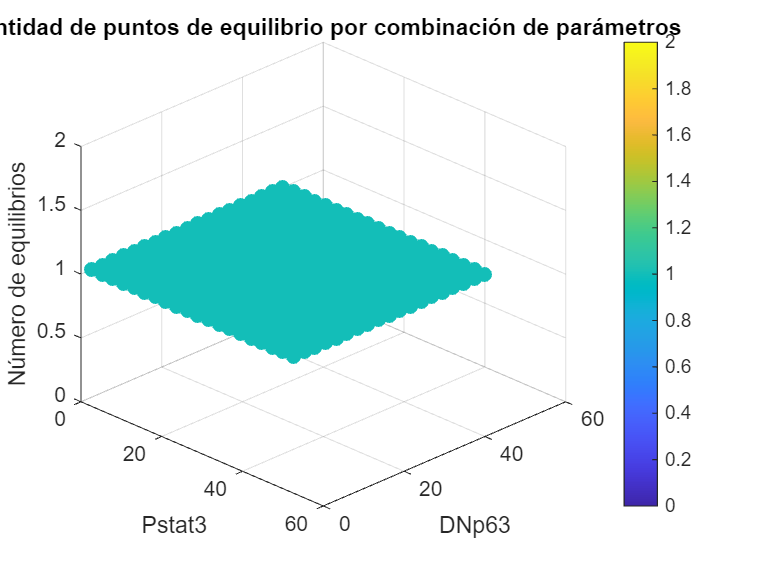


%% Gráfico 3D del número de equilibrios
figure;
scatter3(unique_pairs(:,1), unique_pairs(:,2), num_equilibrios, 50, num_equilibrios, 'filled');
xlabel('Pstat3');
ylabel('DNp63');
zlabel('Número de equilibrios');
title('Cantidad de puntos de equilibrio por combinación de parámetros');
colorbar;
grid on;
view(45, 30);  % Vista en ángulo para mejor percepción 3D

## Graficos coordenada i-ésima vs (Pstat3, DNp63)

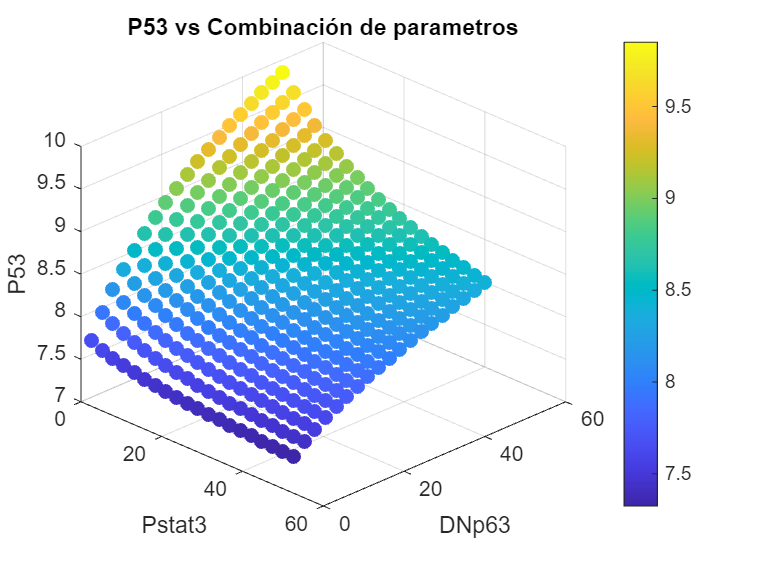

%% Gráfico 3D de P53
figure;
scatter3(resultados(:,1), resultados(:,2), resultados(:,3), 50, resultados(:,3), 'filled');
xlabel('Pstat3');
ylabel('DNp63');
zlabel('P53');
title('P53 vs Combinación de parametros');
colorbar;
grid on;
view(45, 30); 

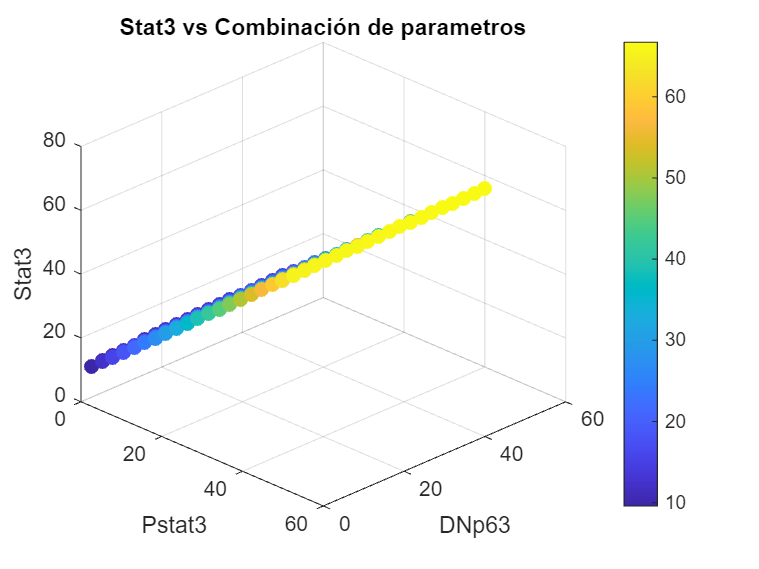


%% Gráfico 3D de Stat3
figure;
scatter3(resultados(:,1), resultados(:,2), resultados(:,4), 50, resultados(:,4), 'filled');
xlabel('Pstat3');
ylabel('DNp63');
zlabel('Stat3');
title('Stat3 vs Combinación de parametros');
colorbar;
grid on;
view(45, 30);

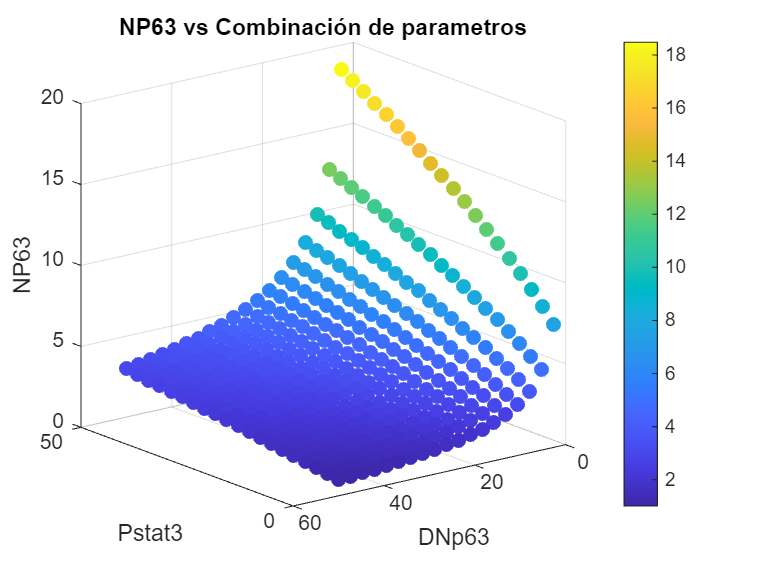


%% Gráfico 3D de NP63
figure;
scatter3(resultados(:,1), resultados(:,2), resultados(:,5), 50, resultados(:,5), 'filled');
xlabel('Pstat3');
ylabel('DNp63');
zlabel('NP63');
title('NP63 vs Combinación de parametros');
colorbar;
grid on;
view(45, 30);  % Vista en ángulo para mejor percepción 3D

## Estabilidad

% Recalcular Jacobiano simbólico una sola vez
J = jacobian([f1, f2, f3], [p53, Stat3, Np63]);

% Inicializar clasificación
tipos = strings(size(resultados,1), 1);

for i = 1:size(resultados,1)
    x = resultados(i,3:5);  % p53, Stat3, Np63
    p = resultados(i,1:2);  % Pstat3, DNp63

    % Sustituir en el Jacobiano
    J_num = double(subs(J, ...
        [p53, Stat3, Np63, Pstat3, DNp63], ...
        [x, p]));

    % Autovalores
    eigs_J = eig(J_num);

    if all(real(eigs_J) < 0)
        tipos(i) = "Atractor";
    elseif any(real(eigs_J) > 0) && any(real(eigs_J) < 0)
        tipos(i) = "Silla";
    elseif all(real(eigs_J) > 0)
        tipos(i) = "Repulsor";
    else
        tipos(i) = "Indeterminado";
    end
end

% Asignar un color a cada tipo
colores = zeros(length(tipos), 3);  % RGB

for i = 1:length(tipos)
    if tipos(i) == "Atractor"
        colores(i,:) = [0 0.6 0];  % verde
    elseif tipos(i) == "Silla"
        colores(i,:) = [1 0.6 0];  % naranja
    elseif tipos(i) == "Repulsor"
        colores(i,:) = [0.8 0 0];  % rojo
    else
        colores(i,:) = [0.5 0.5 0.5];  % gris
    end
end

% Crear el gráfico
figure;
scatter(resultados(:,1), resultados(:,2), 30, colores, 'filled', 'HandleVisibility', 'off');
xlabel('Pstat3');
ylabel('DNp63');
title('Clasificación de los puntos de equilibrio en el plano de parámetros');
grid on;

% Agregar leyenda
hold on;
scatter(NaN, NaN, 30, [0 0.6 0], 'filled', 'DisplayName', 'Atractor');
scatter(NaN, NaN, 30, [1 0.6 0], 'filled', 'DisplayName', 'Silla');
scatter(NaN, NaN, 30, [0.8 0 0], 'filled', 'DisplayName', 'Repulsor');
legend('Location', 'best');
